clear
close all
clc

%% Parameters

a = [1.2272; 1.2272; 1.2272; 1.2272];
A = [380.1327; 380.1327; 380.1327; 380.1327];

gamma = [0.6; 0.7];

g = 981;
rho = 1;

p = [a;A;gamma;g;rho];
%% Nominal operating point

us = [300; 300];

Fbar = [175; 175];

%% Steady state

xguess = 10000*ones(4,1);

options = optimoptions( ...
    'fsolve', ...
    'Display','none');

xs = fsolve( ...
    @(x) FourTankSystem(0,x,us,Fbar,p), ...
    xguess, ...
    options)

xs = 1.0e+04 *

    2.5476
    3.2809
    0.9034
    1.1196



ys = FourTankSensors(xs,p);
zs = FourTankOutputs(xs,p)

zs =    67.0178
   86.3084



%% Simulation settings

Ts = 4;
dt = 0.1;

N = 300;
T = 0:Ts:N*Ts;


## Linearize system

hs = ys; % steady state liquid levels [cm]
lambda = a ./ A .* sqrt(g ./ (2 * hs)); %

A4 = [
    -lambda(1), 0, lambda(3), 0;
    0, -lambda(2), 0, lambda(4);
    0, 0, -lambda(3), 0;
    0, 0, 0, -lambda(4)
    ];

B_u = rho * [
    gamma(1), 0;
    0, gamma(2);
    0, 1 - gamma(2);
    1 - gamma(1), 0
    ];

C_z = [
    1/(rho*A(1)), 0, 0, 0;
    0, 1/(rho*A(2)), 0, 0
    ];

D_z = zeros(2,2);

% Continuous-time multivariable system
sys_c = ss(A4, B_u, C_z, D_z);
G_c = tf(sys_c);


% G11 and G22 chosen due to high gamma (u1 mostly impacts tank 1, u2 tank 2)

G11 = G_c(1,1);
G22 = G_c(2,2);


## Tuning parameters

opt = pidtuneOptions('PhaseMargin', 60);

% Tune P Controllers
C_P1 = pidtune(G11, 'P', opt);
C_P2 = pidtune(G22, 'P', opt);

% Tune PI Controllers
C_PI1 = pidtune(G11, 'PI', opt);
C_PI2 = pidtune(G22, 'PI', opt);

% Tune PID Controllers
C_PID1 = pidtune(G11, 'PID', opt);
C_PID2 = pidtune(G22, 'PID', opt);

% Extract gain parameters for Pump 1 controller
Kc_P  = C_P1.Kp;
Kc_PI = C_PI1.Kp; Ti_PI = C_PI1.Kp / C_PI1.Ki;
Kc_PID = C_PID1.Kp; Ti_PID = C_PID1.Kp / C_PID1.Ki; Td_PID = C_PID1.Kd / C_PID1.Kp;

fprintf('--- Tuned PI Parameters for G11 ---\n');

--- Tuned PI Parameters for G11 ---


fprintf('Kc = %.4f, Ti = %.4f s, Td = %.4f s', Kc_PI, Ti_PI, Td_PID);

Kc = 5.7680, Ti = 38.1512 s, Td = 0.0000 s

## Simulation variables

%% Setpoint profile (with step at halfway)
r_step = [
    70 * ones(1, N/2), 50 * ones(1, N/2);  % Tank 1 setpoint [cm]
    80 * ones(1, N/2), 50 * ones(1, N/2)   % Tank 2 setpoint [cm]
    ];

%% Mimic real physical system with 
umin = [0; 0];
umax = [400; 400];

## --- Deterministic Model P, PI, PID control ---

## P control

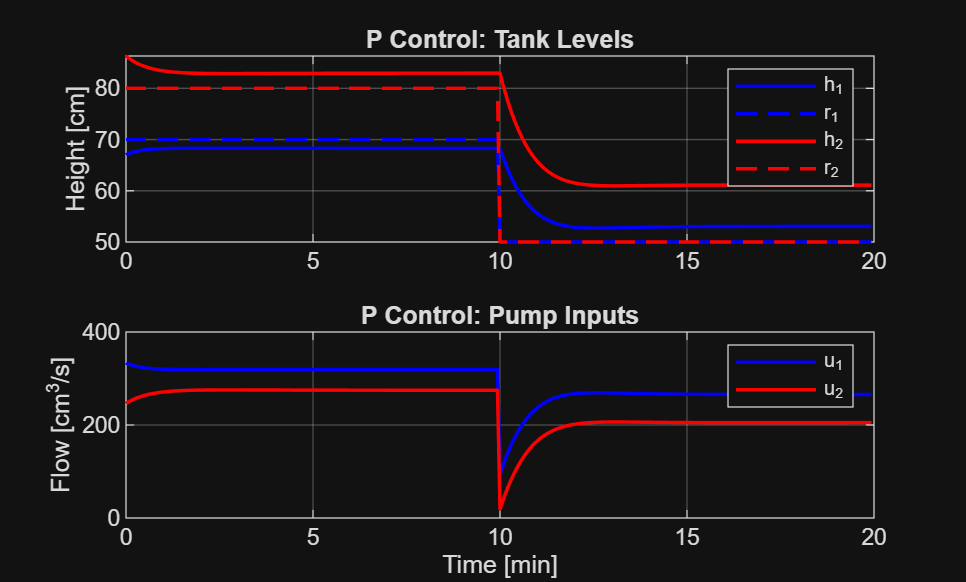

x_P = zeros(4, N+1);
x_P(:,1) = xs;
u_P = zeros(2, N);
z_P = zeros(2, N);

Kc_P1 = C_P1.Kp;
Kc_P2 = C_P2.Kp;

for k = 1:N
    % Measure outputs
    z_P(:,k) = FourTankOutputs(x_P(:,k), p);
    
    % Control error
    e = r_step(:,k) - z_P(:,k);
    
    % Proportional control law with saturation
    v = us + [Kc_P1 * e(1); Kc_P2 * e(2)];
    u_P(:,k) = max(umin, min(umax, v));
    
    % Step dynamics forward
    [~, Xk] = ode15s(@(t,x_val) FourTankSystem(t, x_val, u_P(:,k), Fbar, p), [T(k) T(k+1)], x_P(:,k));
    x_P(:,k+1) = Xk(end,:)';
end

% Plot P Control results
figure;
subplot(2,1,1);
plot(T(1:N)/60, z_P(1,:), 'b', T(1:N)/60, r_step(1,:), 'b--', 'LineWidth', 1.3); hold on;
plot(T(1:N)/60, z_P(2,:), 'r', T(1:N)/60, r_step(2,:), 'r--', 'LineWidth', 1.3);
grid on; ylabel('Height [cm]'); title('P Control: Tank Levels');
legend('h_1', 'r_1', 'h_2', 'r_2');

subplot(2,1,2);
plot(T(1:N)/60, u_P(1,:), 'b', T(1:N)/60, u_P(2,:), 'r', 'LineWidth', 1.3);
grid on; xlabel('Time [min]'); ylabel('Flow [cm^3/s]'); title('P Control: Pump Inputs');
legend('u_1', 'u_2');

## PI Control

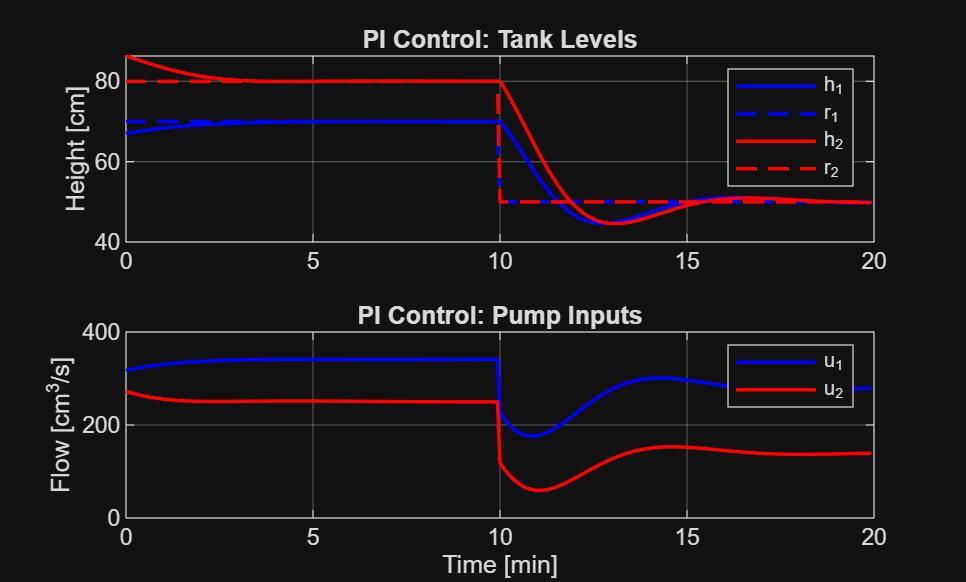


x_PI = zeros(4, N+1);
x_PI(:,1) = xs;
u_PI = zeros(2, N);
z_PI = zeros(2, N);

Kc_PI1 = C_PI1.Kp; Ti_PI1 = C_PI1.Kp / C_PI1.Ki;
Kc_PI2 = C_PI2.Kp; Ti_PI2 = C_PI2.Kp / C_PI2.Ki;

i_state = [0; 0];

for k = 1:N
    % Measure outputs
    z_PI(:,k) = FourTankOutputs(x_PI(:,k), p);

    % Control error
    e = r_step(:,k) - z_PI(:,k);

    % PI control law with saturation
    v = us + [Kc_PI1 * e(1); Kc_PI2 * e(2)] + i_state;
    u_PI(:,k) = max(umin, min(umax, v));

    % Anti-windup integral update
    i_next = i_state + Ts * [Kc_PI1 / Ti_PI1 * e(1); Kc_PI2 / Ti_PI2 * e(2)];
    i_state = max(umin - us, min(umax - us, i_next));

    % Step dynamics forward
    [~, Xk] = ode15s(@(t,x_val) FourTankSystem(t, x_val, u_PI(:,k), Fbar, p), [T(k) T(k+1)], x_PI(:,k));
    x_PI(:,k+1) = Xk(end,:)';
end

% Plot PI Control results
figure;
subplot(2,1,1);
plot(T(1:N)/60, z_PI(1,:), 'b', T(1:N)/60, r_step(1,:), 'b--', 'LineWidth', 1.3); hold on;
plot(T(1:N)/60, z_PI(2,:), 'r', T(1:N)/60, r_step(2,:), 'r--', 'LineWidth', 1.3);
grid on; ylabel('Height [cm]'); title('PI Control: Tank Levels');
legend('h_1', 'r_1', 'h_2', 'r_2');

subplot(2,1,2);
plot(T(1:N)/60, u_PI(1,:), 'b', T(1:N)/60, u_PI(2,:), 'r', 'LineWidth', 1.3);
grid on; xlabel('Time [min]'); ylabel('Flow [cm^3/s]'); title('PI Control: Pump Inputs');
legend('u_1', 'u_2');

## PID control 

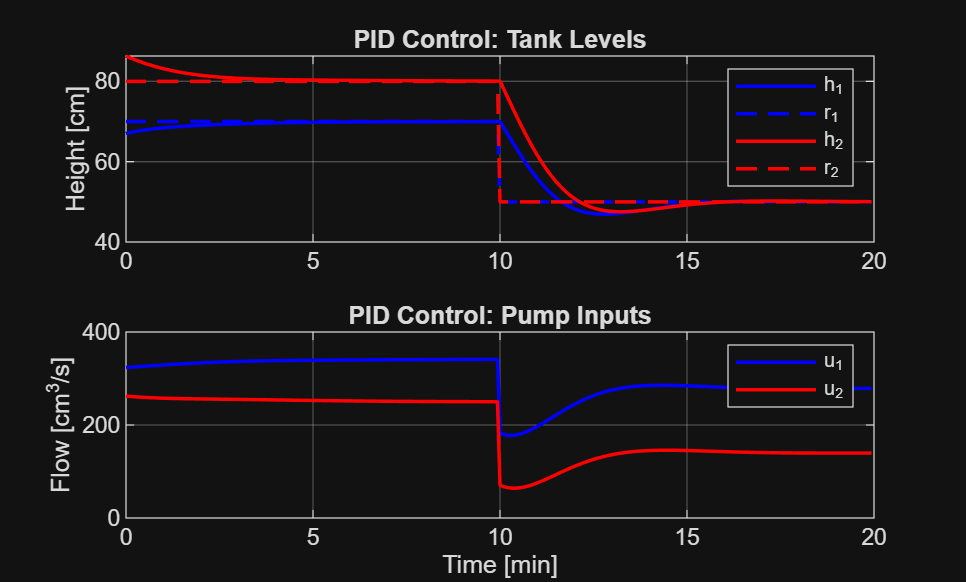

x_PID = zeros(4, N+1);
x_PID(:,1) = xs;
u_PID = zeros(2, N);
z_PID = zeros(2, N);

Kc_PID1 = C_PID1.Kp; Ti_PID1 = C_PID1.Kp / C_PID1.Ki; Td_PID1 = C_PID1.Kd / C_PID1.Kp;
Kc_PID2 = C_PID2.Kp; Ti_PID2 = C_PID2.Kp / C_PID2.Ki; Td_PID2 = C_PID2.Kd / C_PID2.Kp;

i_state = [0; 0];
e_prev  = [0; 0];

for k = 1:N
    % Measure outputs
    z_PID(:,k) = FourTankOutputs(x_PID(:,k), p);

    % Control error
    e = r_step(:,k) - z_PID(:,k);

    % Discrete derivative term
    de = (e - e_prev) / Ts;

    % PID control law with saturation
    v = us + [Kc_PID1 * e(1); Kc_PID2 * e(2)] + i_state + [Kc_PID1 * Td_PID1 * de(1); Kc_PID2 * Td_PID2 * de(2)];
    u_PID(:,k) = max(umin, min(umax, v));

    % Anti-windup integral update
    i_next = i_state + Ts * [Kc_PID1 / Ti_PID1 * e(1); Kc_PID2 / Ti_PID2 * e(2)];
    i_state = max(umin - us, min(umax - us, i_next));
    e_prev = e;

    % Step dynamics forward
    [~, Xk] = ode15s(@(t,x_val) FourTankSystem(t, x_val, u_PID(:,k), Fbar, p), [T(k) T(k+1)], x_PID(:,k));
    x_PID(:,k+1) = Xk(end,:)';
end

% Plot PID Control results
figure;
subplot(2,1,1);
plot(T(1:N)/60, z_PID(1,:), 'b', T(1:N)/60, r_step(1,:), 'b--', 'LineWidth', 1.3); hold on;
plot(T(1:N)/60, z_PID(2,:), 'r', T(1:N)/60, r_step(2,:), 'r--', 'LineWidth', 1.3);
grid on; ylabel('Height [cm]'); title('PID Control: Tank Levels');
legend('h_1', 'r_1', 'h_2', 'r_2');

subplot(2,1,2);
plot(T(1:N)/60, u_PID(1,:), 'b', T(1:N)/60, u_PID(2,:), 'r', 'LineWidth', 1.3);
grid on; xlabel('Time [min]'); ylabel('Flow [cm^3/s]'); title('PID Control: Pump Inputs');
legend('u_1', 'u_2');

## --- Stochastic Model of P, PI, PID control ---

%% Parameters & Noise Setup

model = 'ou';          % Ornstein-Uhlenbeck disturbance model
aF = 0.1;              % Mean-reversion rate
sigmaF = 2.0;          % Unmeasured disturbance noise intensity

% Sensor noise covariance matrix (1.0 cm std dev, R = I_4)
sigma_v = 1.0;                            % Standard deviation [cm]
R = (sigma_v^2) * eye(4);                 % Covariance matrix R
Lv = chol(R, 'lower');

% Time settings for Euler-Maruyama
stepsPerSample = round(Ts/dt);


## P control SDE simulation

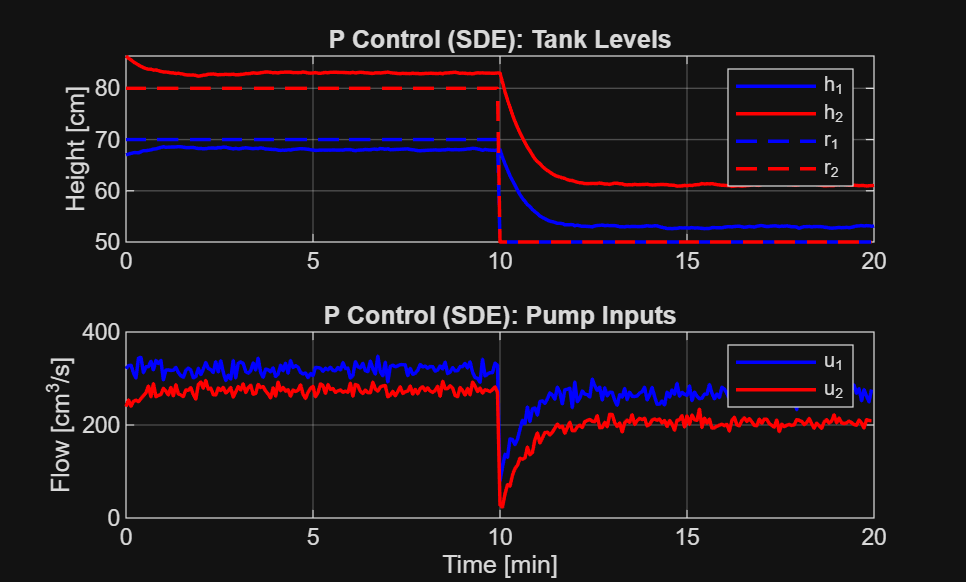

XA_P = zeros(6, N*stepsPerSample + 1);
XA_P(:,1) = [xs; Fbar];

Y_P = zeros(4, N+1);
Z_P = zeros(2, N+1);
u_P = zeros(2, N);

% Initial measurement
x = XA_P(1:4,1);
Y_P(:,1) = FourTankSensors(x,p) + Lv*randn(4,1);
Z_P(:,1) = FourTankOutputs(x,p);

Kc_P1 = C_P1.Kp;
Kc_P2 = C_P2.Kp;

for k = 1:N
    % Control error using noisy measurement Y
    e = r_step(:,k) - Y_P(1:2, k);

    % Proportional control law with saturation
    v = us + [Kc_P1 * e(1); Kc_P2 * e(2)];
    u_P(:,k) = max(umin, min(umax, v));

    % Sub-step Euler-Maruyama loop
    for j = 1:stepsPerSample
        idx = (k-1)*stepsPerSample + j;
        t_curr = (idx-1)*dt;
        xa = XA_P(:, idx);

        [f, sigma] = FourTankSDE(t_curr, xa, u_P(:,k), Fbar, aF, sigmaF, p, model);
        dW = sqrt(dt) * randn(2,1);
        XA_P(:, idx+1) = xa + f*dt + sigma*dW;
    end

    % Sensor reading at sample instant
    iSample = k*stepsPerSample + 1;
    x = XA_P(1:4, iSample);
    Y_P(:, k+1) = FourTankSensors(x,p) + Lv*randn(4,1);
    Z_P(:, k+1) = FourTankOutputs(x,p);
end

% Plot P Control results
figure;
subplot(2,1,1);
plot(T/60, Z_P(1,:), 'b', T/60, Z_P(2,:), 'r', 'LineWidth', 1.3); hold on;
plot(T(1:N)/60, r_step(1,:), 'b--', T(1:N)/60, r_step(2,:), 'r--', 'LineWidth', 1.3);
grid on; ylabel('Height [cm]'); title('P Control (SDE): Tank Levels');
legend('h_1', 'h_2', 'r_1', 'r_2');

subplot(2,1,2);
plot(T(1:N)/60, u_P(1,:), 'b', T(1:N)/60, u_P(2,:), 'r', 'LineWidth', 1.3);
grid on; xlabel('Time [min]'); ylabel('Flow [cm^3/s]'); title('P Control (SDE): Pump Inputs');
legend('u_1', 'u_2');

## PI control SDE Simulation

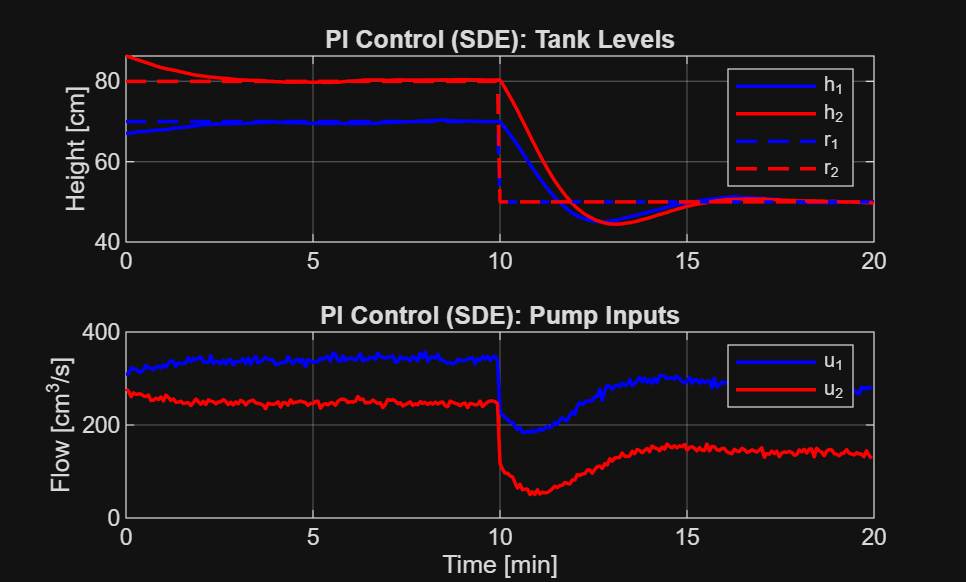

XA_PI = zeros(6, N*stepsPerSample + 1);
XA_PI(:,1) = [xs; Fbar];

Y_PI = zeros(4, N+1);
Z_PI = zeros(2, N+1);
u_PI = zeros(2, N);

x = XA_PI(1:4,1);
Y_PI(:,1) = FourTankSensors(x,p) + Lv*randn(4,1);
Z_PI(:,1) = FourTankOutputs(x,p);

Kc_PI1 = C_PI1.Kp; Ti_PI1 = C_PI1.Kp / C_PI1.Ki;
Kc_PI2 = C_PI2.Kp; Ti_PI2 = C_PI2.Kp / C_PI2.Ki;

i_state = [0; 0];

for k = 1:N
    % Control error from noisy measurement Y
    e = r_step(:,k) - Y_PI(1:2, k);

    % PI law with saturation
    v = us + [Kc_PI1 * e(1); Kc_PI2 * e(2)] + i_state;
    u_PI(:,k) = max(umin, min(umax, v));

    % Anti-windup integral update
    i_next = i_state + Ts * [Kc_PI1 / Ti_PI1 * e(1); Kc_PI2 / Ti_PI2 * e(2)];
    i_state = max(umin - us, min(umax - us, i_next));

    % Sub-step Euler-Maruyama loop
    for j = 1:stepsPerSample
        idx = (k-1)*stepsPerSample + j;
        t_curr = (idx-1)*dt;
        xa = XA_PI(:, idx);

        [f, sigma] = FourTankSDE(t_curr, xa, u_PI(:,k), Fbar, aF, sigmaF, p, model);
        dW = sqrt(dt) * randn(2,1);
        XA_PI(:, idx+1) = xa + f*dt + sigma*dW;
    end

    % Sensor reading at sample instant
    iSample = k*stepsPerSample + 1;
    x = XA_PI(1:4, iSample);
    Y_PI(:, k+1) = FourTankSensors(x,p) + Lv*randn(4,1);
    Z_PI(:, k+1) = FourTankOutputs(x,p);
end

% Plot PI Control results
figure;
subplot(2,1,1);
plot(T/60, Z_PI(1,:), 'b', T/60, Z_PI(2,:), 'r', 'LineWidth', 1.3); hold on;
plot(T(1:N)/60, r_step(1,:), 'b--', T(1:N)/60, r_step(2,:), 'r--', 'LineWidth', 1.3);
grid on; ylabel('Height [cm]'); title('PI Control (SDE): Tank Levels');
legend('h_1', 'h_2', 'r_1', 'r_2');

subplot(2,1,2);
plot(T(1:N)/60, u_PI(1,:), 'b', T(1:N)/60, u_PI(2,:), 'r', 'LineWidth', 1.3);
grid on; xlabel('Time [min]'); ylabel('Flow [cm^3/s]'); title('PI Control (SDE): Pump Inputs');
legend('u_1', 'u_2');

## PID control SDE Simulation

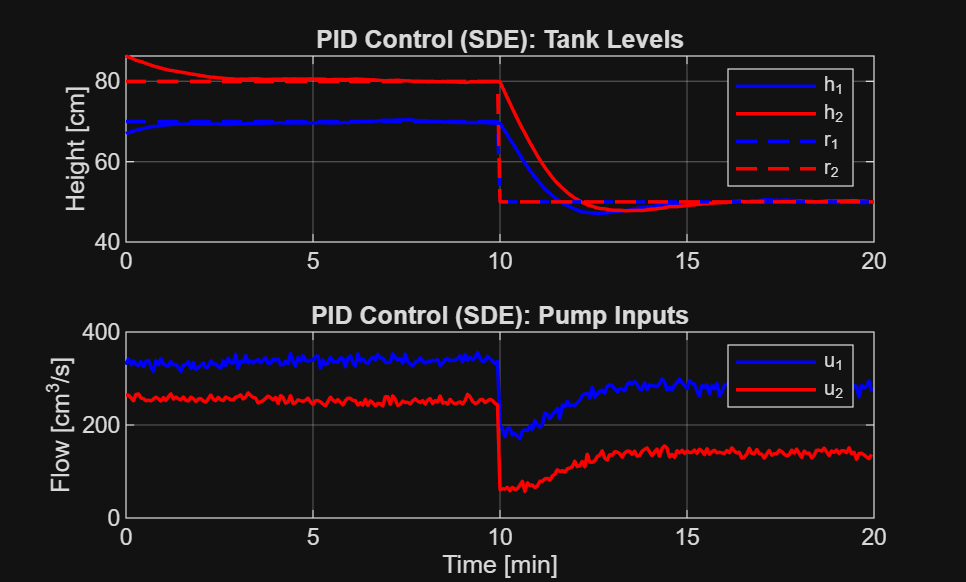

XA_PID = zeros(6, N*stepsPerSample + 1);
XA_PID(:,1) = [xs; Fbar];

Y_PID = zeros(4, N+1);
Z_PID = zeros(2, N+1);
u_PID = zeros(2, N);

x = XA_PID(1:4,1);
Y_PID(:,1) = FourTankSensors(x,p) + Lv*randn(4,1);
Z_PID(:,1) = FourTankOutputs(x,p);

Kc_PID1 = C_PID1.Kp; Ti_PID1 = C_PID1.Kp / C_PID1.Ki; Td_PID1 = C_PID1.Kd / C_PID1.Kp;
Kc_PID2 = C_PID2.Kp; Ti_PID2 = C_PID2.Kp / C_PID2.Ki; Td_PID2 = C_PID2.Kd / C_PID2.Kp;

i_state = [0; 0];
e_prev  = [0; 0];

for k = 1:N
    % Control error from noisy measurement Y
    e = r_step(:,k) - Y_PID(1:2, k);

    % Discrete derivative
    de = (e - e_prev) / Ts;

    % PID law with saturation
    v = us + [Kc_PID1 * e(1); Kc_PID2 * e(2)] + i_state + [Kc_PID1 * Td_PID1 * de(1); Kc_PID2 * Td_PID2 * de(2)];
    u_PID(:,k) = max(umin, min(umax, v));

    % Anti-windup integral update
    i_next = i_state + Ts * [Kc_PID1 / Ti_PID1 * e(1); Kc_PID2 / Ti_PID2 * e(2)];
    i_state = max(umin - us, min(umax - us, i_next));
    e_prev = e;

    % Sub-step Euler-Maruyama loop
    for j = 1:stepsPerSample
        idx = (k-1)*stepsPerSample + j;
        t_curr = (idx-1)*dt;
        xa = XA_PID(:, idx);

        [f, sigma] = FourTankSDE(t_curr, xa, u_PID(:,k), Fbar, aF, sigmaF, p, model);
        dW = sqrt(dt) * randn(2,1);
        XA_PID(:, idx+1) = xa + f*dt + sigma*dW;
    end

    % Sensor reading at sample instant
    iSample = k*stepsPerSample + 1;
    x = XA_PID(1:4, iSample);
    Y_PID(:, k+1) = FourTankSensors(x,p) + Lv*randn(4,1);
    Z_PID(:, k+1) = FourTankOutputs(x,p);
end

% Plot PID Control results
figure;
subplot(2,1,1);
plot(T/60, Z_PID(1,:), 'b', T/60, Z_PID(2,:), 'r', 'LineWidth', 1.3); hold on;
plot(T(1:N)/60, r_step(1,:), 'b--', T(1:N)/60, r_step(2,:), 'r--', 'LineWidth', 1.3);
grid on; ylabel('Height [cm]'); title('PID Control (SDE): Tank Levels');
legend('h_1', 'h_2', 'r_1', 'r_2');

subplot(2,1,2);
plot(T(1:N)/60, u_PID(1,:), 'b', T(1:N)/60, u_PID(2,:), 'r', 'LineWidth', 1.3);
grid on; xlabel('Time [min]'); ylabel('Flow [cm^3/s]'); title('PID Control (SDE): Pump Inputs');
legend('u_1', 'u_2');